# Sample 10-5

## 冗長変換

$\ell_0$ -ノルム最小化

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Redundant transforms

$\ell_0$ -norm minimization

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### 非線形近似の設定

(Settings of non-linear approximation)

% # of Coefs.
K = 32;

% 直交マッチング追跡(OMP)法／マッチング追跡(MP)法
isOmp = true;

### 入力信号の生成

(Generation of input sequence)

% # of input samples
nSamples = 128;

% Random process in AR(1) model
rng('default'); 
w = 0.1*randn(nSamples,1);
w(floor(end/2)) = 1;
u = filter(1,[1 -0.95],w);

### 合成辞書

(Synthesis dictionary)

% Synthesis filters
f0 = [  1 1 ]/2;
f1 = [ -1 1 ]/2;

% (Circular) convolution matrix
nF = max(length(f0),length(f1));
X = [zeros(nF-1,nSamples-nF+1) eye(nF-1); eye(nSamples)]; % Circular extension matrix
C = [zeros(nSamples,nF-1) eye(nSamples) zeros(nSamples,nF-1)]; % Clipping matrix

% Atoms in (circular) convolution matrix
d0 = C*convmtx(f0.',nSamples+nF-1)*X;
d1 = C*convmtx(f1.',nSamples+1)*X;

辞書 (Dictionary) $\mathbf{D}$

% Dictionary D (Global matrix representation of synthesis filter bank)
D = zeros(nSamples,2*nSamples);
D(:,1:2:end) = d0;
D(:,2:2:end) = d1;
disp(D)

    0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

### $\ell_0$ -擬ノルム最小化による非線形近似

(Non-linear approximation  with $\ell_0$ -pseudo-norm minimization)

        
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}\in\mathbb{R}^L}\|\mathbf{s}\|_0\ \mathrm{s.t.}\ \mathbf{v}=\mathbf{Ds}$$


貪欲法による分析処理と係数選択 (Analysis process and coefficient selection by a greedy algorithm)

- マッチング追跡法 (Matching Pursuit; MP)

- 直交マッチング追跡法(Orthogonal MP; OMP

% Initializaton
M  = size(D,2);
e  = ones(M,1);
a  = zeros(M,1);
g  = zeros(M,1);
s  = zeros(M,1);
v = zeros(nSamples,1);
r  = u - v;
supp = [];
k = 0;
while k < K
    % Matching process
    rr = r.'*r;
    for m = 1:M %setdiff(1:M,sup)
        d = D(:,m);
        g(m) = d.'*r; % γm=<dm,r>
        a(m) = g(m)/(d.'*d); % Normalize αm=γm/||dm||^2
        e(m) = rr - a(m); % <r-dm/||dm||^2,r> %
    end

    % Minimum value search (pursuit)
    [~,mmin]= min(e);
    % Update the support
    supp = union(supp,mmin);
    if isOmp % Orthogonal Matching Pursuit
        Ds = D(:,supp);
        s(supp)  = pinv(Ds) * u;
        k = k + 1;
    else % Matching Pursuit
        s(mmin) = s(mmin) + a(mmin); 
        k = length(supp);
    end
    % Synthesis process
    v = D*s;
    % Residual
    r = u - v;
end

近似結果 (Approximation result)

v = D*s;

 近似誤差 (Residual)

r = u - v;

### グラフ描画

 (Graph plot)

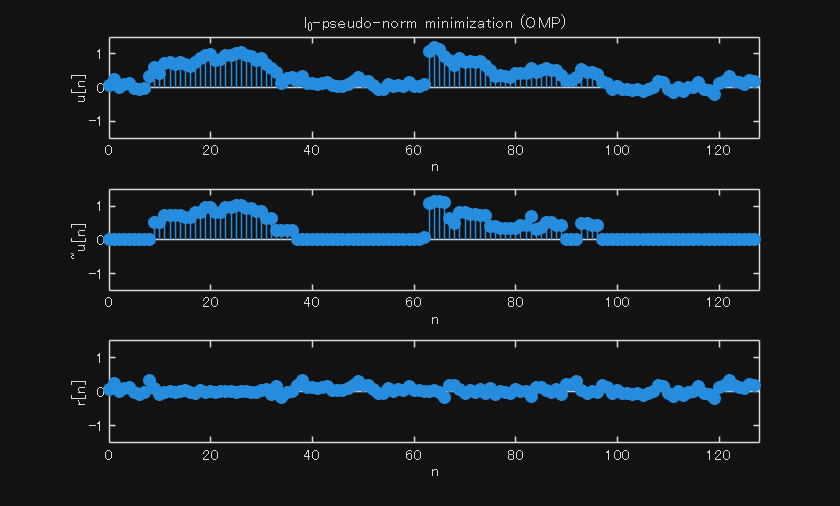

figure(1)

% Input
subplot(3,1,1)
stem(0:nSamples-1,u,'filled')
axis([0 nSamples -1.5 1.5])
xlabel('n')
ylabel('u[n]')
if isOmp
    method = '(OMP)';
else
    method = '(MP)';
end
title(['l_0-pseudo-norm minimization ' method])

% NLA
subplot(3,1,2)
stem(0:nSamples-1,v,'filled')
axis([0 nSamples -1.5 1.5])
xlabel('n')
ylabel('~u[n]')

% Residual
subplot(3,1,3)
stem(0:nSamples-1,r,'filled')
axis([0 nSamples -1.5 1.5])
xlabel('n')
ylabel('r[n]')

MSE評価 (MSE evaluation)

mymse = @(x,y) mean((x(:)-y(:)).^2);
fprintf('mse = %f\n',mymse(u,v));

mse = 0.013168


© Copyright, Shogo MURAMATSU, All rights reserved.